# Molecular Structure

This script illustrates how to calculate the groundstate of a molecule for specified magnetic, electric and electromagnetic fields. Mostly inspired by Till's mathematic notebook, which can also be used to check this code. For a good python library, see diatomic-py.

We will take into account the following terms in the Hamiltonian:

- Hyperfine structure

- Zeeman

- DC - Stark

- AC - Stark

The procedure is as follows: we find a basis for which the hamiltonian is most easily evaluted and then transform it back to a commom basis which we use to sum everything up.

To get the right bases we rely mostly on two classes: AngMom and Basis. AngMom defines the an angular momentum and Basis combines several Angular Momenta into a certain basis.   Let's first define our quantum numbers

- N, mN refer to rotation of the whole molecule

- mI1,mI2 are projections of the fixed nuclear spins I1,I2 onto the external magnetic field

- $I=I_k +I_{\textrm{Rb}}$ - Total nuclear spin

- $F_{i,K} =I_k +N$ & $F_{i,\textrm{Rb}} =I_{\textrm{Rb}} +N$ - Individual atoms coupled to molecular rotation

- 
$$F=I+N$$


We need five sets of bases to calculate the Hamiltonian

- Uncoupled ${\left∣I_K ,I_{\textrm{Rb}} ;\;\;\;N,m_N ,m_{I_K } ,m_{I_{\textrm{Rb}} } \right\rangle}$                                                --> UCBasis

- K-Rb Spin-coupled ${\left∣I_K ,I_{\textrm{Rb}} ;\;\;\;N,m_N ,I,m_I \right\rangle}$                                           --> SCBasis

- K (Rb) coupled with N ${\left∣I_{K\left(\textrm{Rb}\right)} ,N;\;\;F_{i,K\left(\textrm{Rb}\right),} {\;m}_{F_i } \;,\;I_{\textrm{Rb}\left(K\right)} ,\;m_{I_{\textrm{Rb}\left(K\right)} } \right\rangle}$            --> FiKBasis & FiRbBasis

- Total spin coupled with N ${\left∣I_k ,I_{\textrm{Rb}} ,N,I;\;\;F,m_F \right\rangle}$                                    --> FCBasis

We populate the Hamiltonian in whatever basis and then transform it back to the uncoupled (common) basis.

clear all
C = Constants;
Molecule = KRb(40,87);
K = Molecule.Atom1; Rb = Molecule.Atom2;
iRb = AngMom(Rb.spin,"iRb");
iK = AngMom(K.spin,"iK");
N = AngMom([0:1],"N");
I = couple(iK,iRb,"I"); %couple the two nuclear momenta
FiK = couple(iK,N,"FiK"); %couple only a single nucleus to the rotation
FiRb = couple(iRb,N,"FiRb"); %couple only a single nucleus to the rotation
F = couple(I,N,"F");  %fully coupled
UCBasis = Basis(N,iK,iRb);
SCBasis = Basis(N,I); 
FiKBasis = Basis(FiK,iRb);
FiRbBasis = Basis(FiRb,iK);
FCBasis = Basis(F);
nStates = UCBasis.NStates;

Calculate transformations

SCtoUC = calcTransform(SCBasis,UCBasis,I); %gives you U such that UCBasis = U*SCBasis (UC is a sparse matrix) (unitarity is checked)
FCtoSC = calcTransform(FCBasis,SCBasis,F); %gives you U such that SCBasis = U*FCBasis
FiKtoUC = calcTransform(FiKBasis,UCBasis,FiK);
FiRbtoUC = calcTransform(FiRbBasis,UCBasis,FiRb);
FCtoUC = (SCtoUC'*FCtoSC')';

Create Hamiltonian class to keep track of the final matrices and to use its functions

H = Hamiltonian;

## Hyperfine Structure

Let's start with the field-independent, hyperfine structure of the molecule:

### Rigid Rotor Rotational Structure

${H_{\textrm{rot}} =B}_{\textrm{rot}} \left(N\cdot N\right)-D_{\textrm{rot}\;} {{\left(N\cdot N\right)}^2 }^{\;}$, only depends on N, so we can stay in the uncoupled basis

st = UCBasis.getStates("all");
H_rigidRot_UC = H.rotational(st.N,Molecule.Brot,0);

### Scalar Nuclear: Spin-Spin Coupling ($I_k \cdot I_{\textrm{Rb}}$)

$H_{\textrm{ss}}^{\left(0\right)} =c_4 I_K \cdot I_{\textrm{Rb}} =\frac{c_4 }{\;2}\left\lbrack I\left(I+1\right)-I_K \left(I_K +1\right)-I_{\textrm{Rb}} \left(I_{\textrm{Rb}} +1\right)\right\rbrack$, diagonal in the spin-coupled basis

st = SCBasis.getStates("all");
spinSpinScalar = H.scalarNuclear(Molecule.c4,st.I,st.iRb, st.iK);
H_spinspinScalar_UC =  SCtoUC'*spinSpinScalar*SCtoUC;

### Scalar Nuclear: Spin-Rotation Coupling ($N\cdot I_{\textrm{Rb}} \;\textrm{and}\;N\cdot I_K \;$)

$H_{\textrm{sr}} =\sum_{i=K,\textrm{Rb}} c_i N\cdot I_i =\sum_{i=K,\textrm{Rb}} \frac{c_i }{\;2}\left\lbrack F\left(F+1\right)-N\left(N+1\right)-I_i \left(I_i +1\right)\right\rbrack$. The terms are diagonal in their respective individual spin-rotation coupled basis (FiK & FiRb bases)

st = FiKBasis.getStates("all");
hsrK = H.scalarNuclear(Molecule.c1,st.FiK,st.N, st.iK);
st = FiRbBasis.getStates("all");
hsrRb = H.scalarNuclear(Molecule.c2,st.FiRb,st.N, st.iRb);
H_spinRot_UC = FiKtoUC'*hsrK*FiKtoUC + FiRbtoUC'*hsrRb*FiRbtoUC;

### Tensor Nuclear: Spin-Spin Coupling

$H_{\textrm{ss}}^{\left(2\right)} ={-c}_3 I_K \cdot \mathit{\mathbf{T}}\cdot \;I_{\textrm{Rb}} =-c_3 \sqrt{\;6}T^2 \left(C\right)\cdot T^2 \left(I_1 ,I_2 \right)$, where the elements $T_q^2 \left(C\right)=C_q^2 \left(\theta \;,\phi \;\right)$ and $T^2 \left(I_1 ,I_2 \right)$ is the second-rank tensor product of the two nuclear momentum vectors (see Eq. 5b from [5]). $C_q^2$ are the Racah-normalised forms of the spherical harmonic of order 2. The coupling is about 50 times smaller than the scalar spin-spin-coupling, but on the the same order as the spin-rotation coupling.

Molecule.c3/Molecule.c4 %tensor vs scalar spin-spin

ans = 0.0237

Molecule.c3/Molecule.c1 %tensor spin-spin vs scalar spin-rot

ans = 2

H_spinspinTensor_UC = H.tensorNuclear(Molecule.c3,iK,iRb, UCBasis); %create Hamiltonian

### Nuclear Electric Quadrupole Coupling ($\sum_{i=1,2} {\textrm{eV}}_i Q_i$)

From Brown and Carrington (eq. 8.287), we know that in a weak field, the Hamiltonian can be diagonalised in the basis in which one of the nuclei is coupled to the rotation of the molecule: 


$$H_Q =\sum_{i=K,\textrm{Rb}} \frac{{\textrm{eV}}_i Q_i }{2I_i \left(2I_i -1\right)\left(2N-1\right)\left(2N+3\right)\;}\left\lbrack \frac{3}{4}\left\lbrace {\mathit{\mathbf{I}}}_{\mathit{\mathbf{i}}}^2 +{\mathit{\mathbf{N}}}^2 -{{\mathit{\mathbf{F}}}_i }^2 \right\rbrace \left(\left\lbrace {\mathit{\mathbf{I}}}_{\mathit{\mathbf{i}}}^2 +{\mathit{\mathbf{N}}}^2 -{{\mathit{\mathbf{F}}}_i }^2 \right\rbrace -1\right)-I_i \left(I_i +1\right)*N\left(N+1\right)\right\rbrack$$


$V_{i\;}$ is the electric field gradient at the position of nucleus $i$ and $eQ_{i\;}$is its nuclear quadrupole moment. The other terms come from spherical tensor algebra.

st = FiKBasis.getStates("all");
hQK = H.electricQuadrupole(Molecule.Q1,st.N,st.iK,st.FiK);
st = FiRbBasis.getStates("all");
hQRb = H.electricQuadrupole(Molecule.Q2,st.N,st.iRb,st.FiRb);
H_nuclearElectric_UC = FiKtoUC'*hQK*FiKtoUC + FiRbtoUC'*hQRb*FiRbtoUC;

## Zeeman (Magnetic Field Dependence)

This term is diagonal in the uncoupled basis set (only the spin projections matter)


$$H_z =-\sum_{i=K,\textrm{Rb}} \;g_{i\;} m_{i\;} \left(1-\sigma {\;}_{i\;} \right)\mu_{N_{i\;} } B-g_r \mu {\;}_{N_{\textrm{KRb}} \;} m_N B$$


st = UCBasis.getStates("all");
gK = K.gFactor; sigK = K.nuclearShielding;
gRb = Rb.gFactor; sigRb = Rb.nuclearShielding;
H_zeeman_UC = H.makeZeeman(gK*(1-sigK)*C.muN,st.miK) + H.makeZeeman(gRb*(1-sigRb)*C.muN,st.miRb) + H.makeZeeman(Molecule.gr*C.muN,st.mN);

## Stark

### DC (Static Electric Field Dependence)

st = UCBasis.getStates("all");
H_dc_UC = H.makeDCStark(Molecule.d0,st.N,st.mN, dir = [0,0,1]);

### AC (Light Shifts)

Visualise the contributions to the Hamiltonian as a final check

H.hyperfine = H_spinspinScalar_UC + H_spinRot_UC + H_rigidRot_UC + H_spinspinTensor_UC + H_nuclearElectric_UC; 
fMat = figure(13);clf;
set(fMat,'Visible','on');
t = tiledlayout(fMat, 'flow');
colormap(colormaps.bluewhitered);
nexttile(); imagesc((H_rigidRot_UC)/C.h); title("Rigid-Rotor"); clim([-1,1]*3e9)
nexttile(); imagesc(H_spinspinScalar_UC/C.h); title("Spin-Spin (Scalar)");%clim([-1,1])
nexttile(); imagesc(H_spinRot_UC/C.h); title("Spin-Rotation (Scalar)");
nexttile(); imagesc(H_spinspinTensor_UC/C.h); title("Spin-Spin (Tensor)");
nexttile(); imagesc(H_nuclearElectric_UC/C.h); title("Nuclear Electric");clim([-1,1]*3e5)
nexttile(); imagesc(1e-4*H_zeeman_UC/C.h); title("Zeeman");
nexttile(); imagesc(H_dc_UC/C.h); title("DC Stark");clim([-1,1]*3e3)
for k = 1:length(t.Children)
    nexttile(k);
    % colorbar
    pbaspect([1,1,1])
    grid off
end
nexttile(); spy(H.hyperfine/C.h,'k'); title("Hyperfine");clim([-1,1]*3e9)

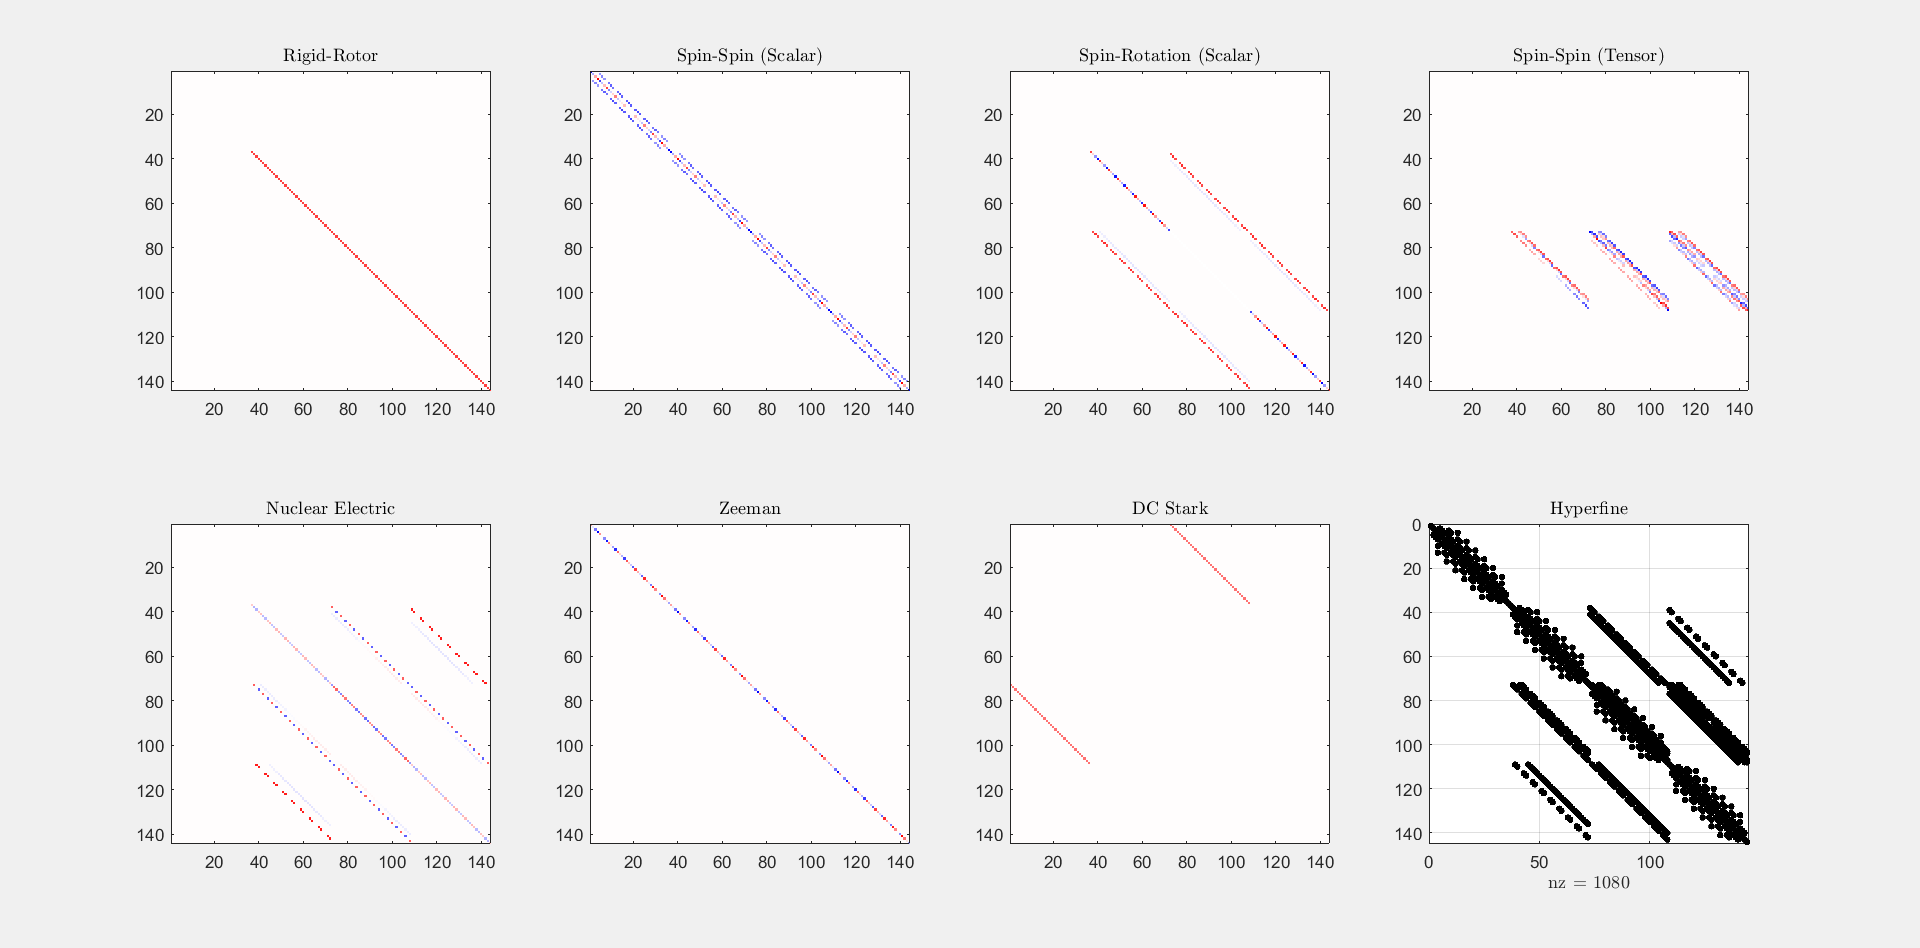

H.hyperfine = H_spinspinScalar_UC + H_rigidRot_UC + H_nuclearElectric_UC + H_spinRot_UC; + H_spinspinTensor_UC;

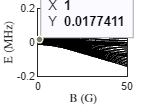


Es = 0;linspace(0,1600,51)*1e2; %V/m
Bs = linspace(0,50,101)*1e-4;
energyMap = nan(length(Es), length(Bs),nStates);
% statesMap = nan(length(Es), length(Bs),nStates,nStates);
for l = 1:length(Es)
    for k = 1:length(Bs)
        B = Bs(k);
        E = Es(l);
        Ham = H.hyperfine + B*H_zeeman_UC + E*H_dc_UC; %why this sqrt(2) necessary to coincide with diatomic-py?
        [V,D] = eig(full(Ham/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
        [d,sortIdx] = sort(real(D));
        energyMap(l,k,:)=d;        
        % statesMap(l,k,:,:) = V(:,sortIdx);
    end
end
sMax = 36;
energy = (squeeze(energyMap(1,:,1:sMax)));
% currStates = squeeze(statesMap(:,1,:,1:sMax));

figure(4);clf; %Zeeman Map
title("Zeeman Map")
ps = plot(Bs*1e4,energy(:,:)*1e-6, '-', "Color","k", MarkerSize=2, LineWidth=0.5, MarkerFaceColor="k");
% ps = plot(Es*1e-2,energydf(:,:)*1e-6, '-', "Color","k", MarkerSize=2, LineWidth=0.5, MarkerFaceColor="k");
ylabel("E (MHz)")
xlabel("B (G)")
xlim([min(Bs),max(Bs)]*1e4)
% ylim([-1,1]*5e-3)
%Seems like a factor 1/sqrt(2) in the dc-stark hamiltonian gives the same answer as diatomic-py

% ylim([-1,1]*0.03)


Es = linspace(0,1600,51)*1e2; %V/m
Bs = 0;
energyMap = nan(length(Es), length(Bs),nStates);
% statesMap = nan(length(Es), length(Bs),nStates,nStates);
for l = 1:length(Es)
    for k = 1:length(Bs)
        B = Bs(k);
        E = Es(l);
        Ham = H.hyperfine + B*H_zeeman_UC + E*H_dc_UC; %why this sqrt(2) necessary to coincide with diatomic-py?
        [V,D] = eig(full(Ham/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
        [d,sortIdx] = sort(real(D));
        energyMap(l,k,:)=d;        
        % statesMap(l,k,:,:) = V(:,sortIdx);
    end
end
energy = (squeeze(energyMap(:,1,1:sMax)));
energydf = energy - mean(energy,2);

figure(5); clf; %Stark Map
title("Stark Map")
ps = plot(Es*1e-2,energydf(:,:)*1e-6, '-', "Color","k", MarkerSize=2, LineWidth=0.5, MarkerFaceColor="k");
ylabel("E (MHz)")
xlabel("E (V/cm)")
xlim([min(Es),max(Es)]*1e-2)

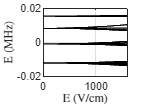

alpha_P=100; alpha_s=33; muE=288958.00; %from Till's mathematica notebook

#### References

[1] Tills notebook

[2] Aldegunde et al (2008): https://doi.org/10.1103/PhysRevA.78.033434

[3] Krems

[4] Brown and Carrington

[5] Diatomic-py. https://doi.org/10.1016/j.cpc.2022.108512